# 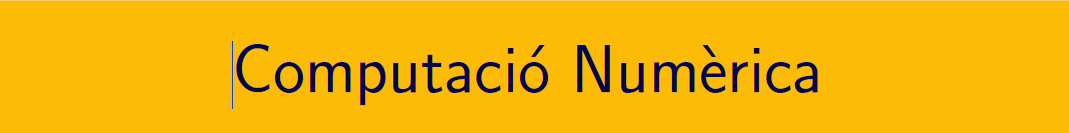

================================================================================

# Pràctica 10. Integració aproximada de funcions i dades.

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab9.pdf i en el document CN_full6.pdf, els podeu trobar en el campus virtual. 

## 1 APRENEM .....

### 1.1 MATLAB® - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html). Per al mètode de Simpson, podeu fer ús de l'expressió  $ S(f,h)=\displaystyle\frac{4}{3}T\left(f,\frac{h}{2}\right)-\frac{1}{3}T(f,h)$que relaciona la fórmula dels trapezis i la regla de Simpson. També podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files) (revisar el codi)

### 1.2 MATLAB® - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### 1.3 MATLAB® - Integració adaptativa

La partició de l'interval d'integració es construiex de tal manera que  `abs(q - Q) <= max(AbsTol,RelTol*abs(q)), amb q el valor calculat i Q el valor exacte. Consulteu `[integral](https://www.mathworks.com/help/matlab/ref/integral.html) en la documentació de MATLAB®

Cleve Moler, entre els seus codis del llibre *Numerical computing with Matlab* ens ha preparat una explicació gràfica del procediment. 

% quadgui(@(x)humps(x),0,1,1.0e-2)    % pretent fent simpson
integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

### 1.4  MATLAB® - Monte Carlo Simulation

Una petita introducció dels mètodes en MATLAB® es pot consultar a l'enllaç següent: [https://es.mathworks.com/discovery/monte-carlo-simulation.html](https://es.mathworks.com/discovery/monte-carlo-simulation.html)

Integració aproximada pel mètode de Montecarlo:  una explicació en el video del professor Craig McNeile a youtube [https://www.youtube.com/watch?v=AaCeUpSFHAk](https://www.youtube.com/watch?v=AaCeUpSFHAk) 

Que s'enten per Monte Carlo Simulation? Una classe del professor John Guttag en el Mit Course: [Introduction to Computational Thinking and Data Science](https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-0002-introduction-to-computational-thinking-and-data-science-fall-2016/). Disponible a l'enllaç [https://www.youtube.com/watch?v=OgO1gpXSUzU](https://www.youtube.com/watch?v=OgO1gpXSUzU)

## 2 PRACTIQUEM ....

### Exercici 1. Aplicació dades discretes

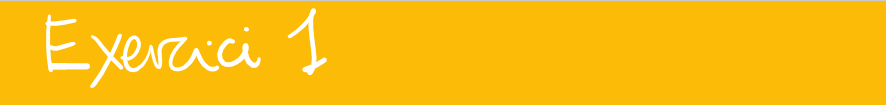

Trobeu la distància que ha recorregut un mòvil a partit de les dades de la següent taula

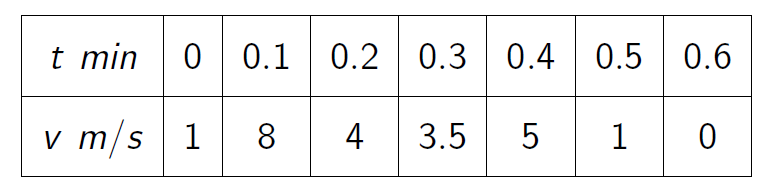

format shortG
time = linspace(0,0.6,7);
vel = [1 8 4 3.5 5 1 0];
t = time*60;

- Representa gràficament les dades de la taula

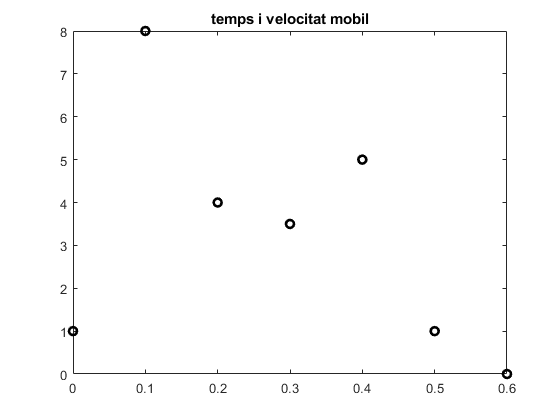

plot(time,vel,'ko', 'LineWidth',2), title('temps i velocitat mobil')

- Explica l'estratègia i dona el resultat pel mètode del punt mig

h = 0.2*60;
w = [0 1 0 1 0 1 0];    % només compten els punts mitjos
I_m = h*sum(w.*vel)

I_m =    150


- Explica l'estratègia i dona el resultat pel mètode dels trapezis

I_t = trapz(t,vel)

I_t =           132


- Explica l'estratègia i dona el resultat pel mètode de Simpson

w = [1 4 2 4 2 4 1];    % pesos (podia fer un bucle)
h = 0.1*60;
I_s = h/3*sum(w.*vel)

I_s =    138


### Exercici 2. Aplicació per funcions - Fórmules simples

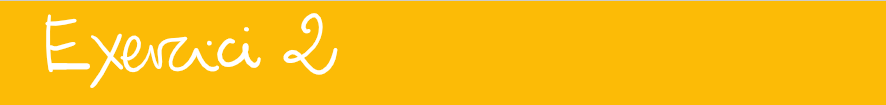

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


vc = pi/2

vc =        1.5708


f = @(x)2./(1+x.^2);

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

a = 0; b = 1; h = b-a

h =      1


I_pm = h*f((a+b)/2), dc = abs(vc-I_pm)

I_pm =           1.6


dc =      0.029204


I_pm = midp(f,0,1,1)

I_pm =           1.6


- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$(simple)

a = 0; b = 1; h = b-a;
I_t = h*(f(a)+f(b))/2, dc = abs(vc-I_t)

I_t =           1.5


dc =      0.070796


I_t = trap(f,0,1,1)

I_t =           1.5


x = [0,1]; y = f(x);
I_t = trapz(x,y)

I_t =           1.5


- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

a = 0; b = 1; h = (b-a)/2;
I_t = h*(f(a)+4*f((a+b)/2)+f(b))/3, dc = abs(vc-I_t)

I_t =        1.5667


dc =     0.0041297


I_s = simp(f,0,1,1)

I_s =        1.5667


### Exercici 3. Aplicació per funcions - Fórmules compostes

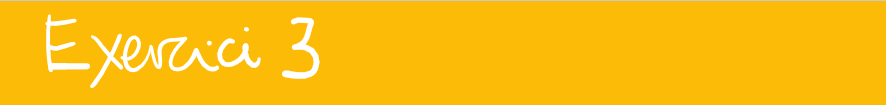

Podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files)

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


clearvars;
f = @(x)2./(1+x.^2);
vc = pi/2;

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

% 0-*-1/4-*-1/2-*-3/4-*-1
a = 0; b = 1; n = 4;
h = (b-a)/n;
x = a+h/2:h:b;
I_pm = sum(f(x))*h,dc = abs(vc-I_pm)

I_pm =        1.5734


dc =     0.0026039


I_pm = midp(f,0,1,4)

I_pm =        1.5734


- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

a = 0; b = 1;
n = 4;
h = (b-a)/n;
x = a:h:b;
y = f(x);
I_t = trapz(x,y),dc = abs(vc-I_t)

I_t =        1.5656


dc =     0.0052081


I_t = trap(f,0,1,4)

I_t =        1.5656


- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (2 subintervals)

% 0-1/2-1
a = 0; b = 1;
n = 2;
h = (b-a)/(2*n);
x = a:h:b;
y = f(x);
w = [1 4 2 4 1];
I_s = sum(w.*y)*h/3, dc = abs(vc-I_s)

I_s =        1.5708


dc =    1.2013e-05


I_s = simp(f,0,1,2)

I_s =        1.5708


dc = abs([I_pm,I_t,I_s]-vc) % error

dc =     0.0026039    0.0052081   1.2013e-05


### Exercici 4. Funcions amb singularitats

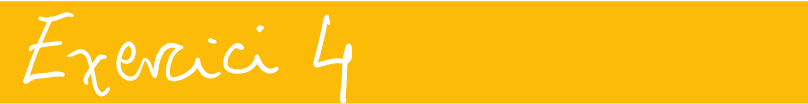

Calculeu $\displaystyle \int_0^{1} \frac{\sin t}{t}\,dt  \approx 0.946083070367 \pm 0.5e\!-\!12$

- Valor correcte

vc =  0.946083070367;
f = @(t)sin(t)./t;

- Regla del punt mig composta. Quants subintervals cal pendre?

% funció oberta
I_pm = midp(f,0,1,100)

I_pm =       0.94608


dc = abs(I_pm - vc)

dc =    1.2549e-06


- Regla dels trapezis composta. Quants subintervals cal pendre?

% funció tancada (problema t = 0)
I_t = trap(f,0,1,10)

I_t =    NaN


% 1 solució (no bona)
I_t = trap(f,0.01,1,10)

I_t =       0.93584


% 2 solució
I_t = trap(@myF,0,1,10)

I_t =       0.94583


% Quants subintervals?
% ((b-a)^3/24)*h^2*f''()
% |(1/24*n^2)*f''(x)| < 0.5e-12         PD: caldria fer una funció que donat 0.5e-12 retorni el nombre de subintervals
dc = abs(I_t - vc)

dc =      0.000251


### Exercici 5. Mètode de Romberg

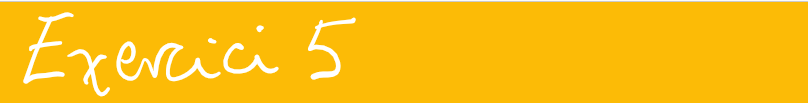

Calculeu mitjançant romberg$\displaystyle \int_0^{0.8} \frac{\sin t}{t}\,dt  \approx 0.772095 \pm 0.5e\!-\!6$

Apliqueu la taula d'extrapolació de romberg (podeu fer ús de [romberg.m](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) o un altre, verifiqueu el  vostre codi amb la taula següent)

format longG
vc = integral(@(x)myF(x),0,0.8,'RelTol',1e-8,'AbsTol',1e-16);
r = romberg(@myF,0,0.8,4)

r =          0.758678045449761                         0                         0                         0
         0.768757365033531         0.772117138228121                         0                         0
         0.771262171110172         0.772097106469052         0.772095771018448                         0
         0.771887443653348         0.772095867834406         0.772095785258763           0.7720957854848


abs(round(r - tril(vc*ones(size(r))),3,'significant'))

ans =                     0.0134                         0                         0                         0
                   0.00334                  2.14e-05                         0                         0
                  0.000834                  1.32e-06                  1.45e-08                         0
                  0.000208                  8.24e-08                  2.23e-10                   2.8e-12


Resposta 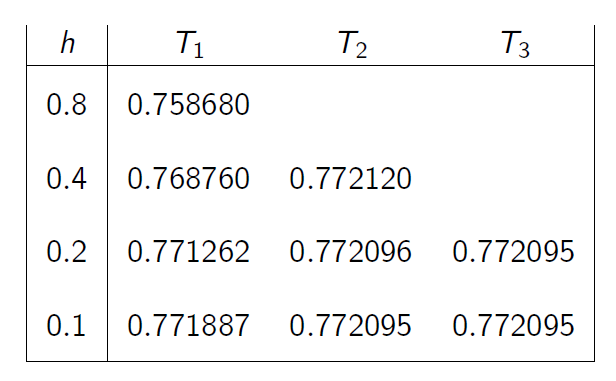 

### Exercici 6. Mètode de Montecarlo

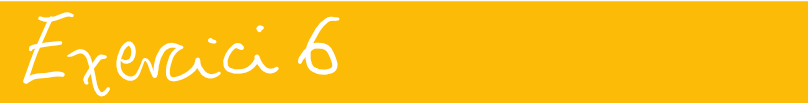

 Calculeu el valor de    $\displaystyle\int_0^1 x dx = 1/2$ 

- Tipus I (valor esperat)

format short
g = @(x)x;
m = 1000000;
a = 0; b = 1;
x = a+(b-a)*rand(m,1);
y = g(x);
I_m = (b-a)/m*sum(y)

I_m = 0.5001

dc = abs(I_m - 1/2), ordre = 1/sqrt(m)

dc = 1.2629e-04

ordre = 1.0000e-03

 Calculeu l'àrea d'un cercle de centre (0,0) i radi 1

- Tipus II (hit or miss)

% sector 
m = 100000;
% x^2+^2 <= 1
f =  @(x,y)x.^2+y.^2;
x = rand(m,1);
y = rand(m,1);
k = 0;
for i = 1:m
    if f(x(i),y(i)) <= 1
        k = k+1;
    end
end
I = k/m

I = 0.7843

dc = abs(pi-4*I)

dc = 0.0044

% tot el cercle
m = 100000;
% x^2+^2 <= 1
f =  @(x,y)x.^2+y.^2;
a = -1; b = 1;
x = a+(b-a)*rand(m,1);
y = a+(b-a)*rand(m,1);
k = 0;
for i = 1:m
    if f(x(i),y(i)) <= 1
        k = k+1;
    end
end
I = (b-a)*2*k/m

I = 3.1372

dc = abs(pi-I)

dc = 0.0044

## 3 AUTOAVALUACIÓ ....

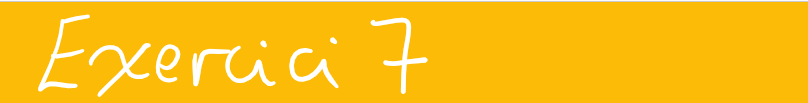

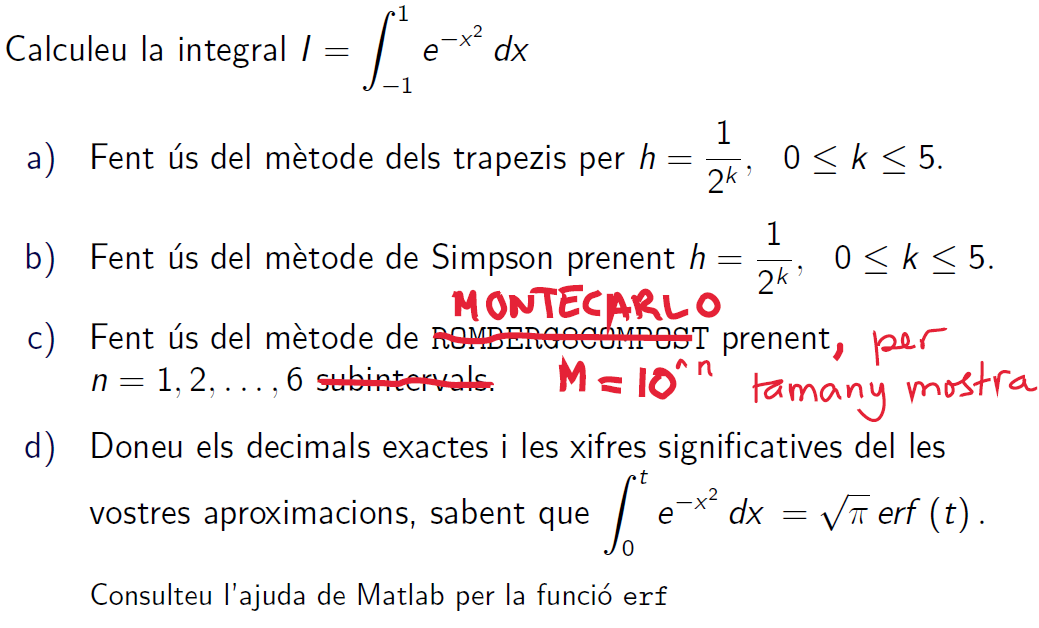

f = @(x) exp(-x.^2);
ve = integral(f,-1,1)

ve =           1.49364826562485


% Métode punt mig
k = 0:5; a = -1; b = 1;
my_midp(f,a,b,k);

    k      h             f(_)                 error            xifres
    _    ______    ________________    ____________________    ______

    0         2                   2       0.506351734375146      0   
    1         1    1.55760156614281      0.0639533005179558      0   
    2       0.5     1.5091958875444       0.015547621919545      1   
    3      0.25    1.49749426378202     0.00384599815716435      2   
    4     0.125     1.4946071574615    0.000958891836641884      2   
    5    0.0625    1.49388782503273    0.000239559407880119      3   



% Métode de Trapezis
k = 0:5; a = -1; b = 1;
my_trap(f,a,b,k);

    k       h             f(_)                 error            xifres
    _    _______    ________________    ____________________    ______

    0          1    1.36787944117144       0.125768824453412      0   
    1        0.5    1.46274050365713       0.030907761967728      1   
    2       0.25    1.48596819560076     0.00768007002409155      1   
    3      0.125    1.49173122969139     0.00191703593346326      2   
    4     0.0625    1.49316919357644    0.000479072048411355      3   
    5    0.03125    1.49352850930459    0.000119756320265507      3   



% Mètode de Simpson
k = 0:5; a = -1; b = 1;
my_simp(f,a,b,k);

    k       h             f(_)                 error            xifres
    _    _______    ________________    ____________________    ______

    0          1    1.57858629411429       0.084938028489441      0   
    1        0.5    1.49436085781902    0.000712592194166639      2   
    2       0.25    1.49371075958197    6.24939571203242e-05      3   
    3      0.125    1.49365224105493    3.97543007935042e-06      5   
    4     0.0625    1.49364851487146    2.49246606687237e-07      6   
    5    0.03125    1.49364828121397    1.55891162201272e-08      7   



% Mètode de Montecarlo
format longG
a = -1; b = 1; k = 1:6;
my_montecarlo(f,a,b,k);

    k       M             f(_)                 error            xifres
    _    _______    ________________    ____________________    ______

    1         10    1.57920394646296      0.0855556808381064      0   
    2        100    1.46873208149388      0.0249161841309773      1   
    3       1000    1.51131518050201      0.0176669148771536      1   
    4      10000    1.49151117314149     0.00213709248336502      2   
    5     100000    1.49350257087787    0.000145694746984448      3   
    6    1000000    1.49337125348468    0.000277012140169619      3   



function y = myF(x)
y = sin(x)./x;
if isnan(y)
    y = 1;
end
end